Model Development

%% Physics-Informed Neural Network (PINN) for 2D Navier-Stokes
clear; clc; rng(42);

% --- 1. Physical Parameters and Loss Weightings ---
nu    = 0.01;      % Kinematic viscosity (m^2/s)
U_in  = 1.0;       % Inlet velocity (m/s)
w_pde = 1.0;       % Weight for Navier-Stokes residuals
w_bc  = 10.0;      % Weight for boundary conditions
w_data= 5.0;       % Weight for empirical supervised data

% Domain Bounds: [x_min, x_max, y_min, y_max]
domain = [0.0, 2.0, -0.5, 0.5];

% --- 2. Construct Multilayer Perceptron (MLP) Architecture ---
numInputs  = 2;    % Spatial coordinates: [x, y]
numOutputs = 3;    % State variables: [u, v, p]
numHidden  = 64;   % Neurons per hidden layer

layers = [
    featureInputLayer(numInputs, 'Name', 'coords_in')
    
    fullyConnectedLayer(numHidden, 'Name', 'fc1')
    tanhLayer('Name', 'act1')
    
    fullyConnectedLayer(numHidden, 'Name', 'fc2')
    tanhLayer('Name', 'act2')
    
    fullyConnectedLayer(numHidden, 'Name', 'fc3')
    tanhLayer('Name', 'act3')
    
    fullyConnectedLayer(numHidden, 'Name', 'fc4')
    tanhLayer('Name', 'act4')
    
    fullyConnectedLayer(numOutputs, 'Name', 'state_out')
];

net = dlnetwork(layers);

% --- 3. Generate Collocation and Boundary Datasets ---
% Interior Collocation Points (Latin Hypercube / Uniform sampling)
N_f = 4000;
x_f = domain(1) + (domain(2) - domain(1)) * rand(N_f, 1, 'single');
y_f = domain(3) + (domain(4) - domain(3)) * rand(N_f, 1, 'single');

% Boundary Points
N_b = 200;
% Inlet: x = 0, y in [-0.5, 0.5]
bc_inlet_x = repmat(domain(1), N_b, 1);
bc_inlet_y = domain(3) + (domain(4) - domain(3)) * rand(N_b, 1, 'single');
bc_inlet_u = repmat(U_in, N_b, 1);
bc_inlet_v = zeros(N_b, 1, 'single');

% Walls: y = -0.5 and y = 0.5 (No-slip)
bc_wall_x = domain(1) + (domain(2) - domain(1)) * rand(2*N_b, 1, 'single');
bc_wall_y = [repmat(domain(3), N_b, 1); repmat(domain(4), N_b, 1)];
bc_wall_u = zeros(2*N_b, 1, 'single');
bc_wall_v = zeros(2*N_b, 1, 'single');

% Outlet: x = 2.0 (Zero gauge pressure)
bc_outlet_x = repmat(domain(2), N_b, 1);
bc_outlet_y = domain(3) + (domain(4) - domain(3)) * rand(N_b, 1, 'single');
bc_outlet_p = zeros(N_b, 1, 'single');

% Convert to dlarray formatted as 'CB' (Channels x Batch)
colloc_pts = dlarray([x_f, y_f]', 'CB');

inlet_pts  = dlarray([bc_inlet_x, bc_inlet_y]', 'CB');
inlet_val  = dlarray([bc_inlet_u, bc_inlet_v]', 'CB');

wall_pts   = dlarray([bc_wall_x, bc_wall_y]', 'CB');
wall_val   = dlarray([bc_wall_u, bc_wall_v]', 'CB');

outlet_pts = dlarray([bc_outlet_x, bc_outlet_y]', 'CB');
outlet_val = dlarray(bc_outlet_p', 'CB');

% --- 4. Training Loop Setup (Adam Optimizer) ---
numEpochs      = 1000;
learningRate   = 1e-3;
averageGrad    = [];
averageSqGrad  = [];

fprintf('Beginning PINN training with embedded Navier-Stokes loss...\n');

Beginning PINN training with embedded Navier-Stokes loss...



for epoch = 1:numEpochs
    % Evaluate objective and backpropagate gradients
    [loss, grad, l_pde, l_bc] = dlfeval(@computeTotalLoss, net, colloc_pts, ...
        inlet_pts, inlet_val, wall_pts, wall_val, outlet_pts, outlet_val, ...
        nu, w_pde, w_bc);
    
    % Update MLP parameters via Adam
    [net, averageGrad, averageSqGrad] = adamupdate(net, grad, ...
        averageGrad, averageSqGrad, epoch, learningRate);
    
    % Display optimization progress
    if mod(epoch, 100) == 0 || epoch == 1
        fprintf('Epoch: %4d | Total Loss: %.4e | PDE Residual: %.4e | BC Loss: %.4e\n', ...
            epoch, double(gather(extractdata(loss))), ...
            double(gather(extractdata(l_pde))), ...
            double(gather(extractdata(l_bc))));
    end
end

Epoch:    1 | Total Loss: 8.8541e+00 | PDE Residual: 1.7565e-01 | BC Loss: 8.6785e-01
Epoch:  100 | Total Loss: 9.1248e-01 | PDE Residual: 2.3622e-01 | BC Loss: 6.7626e-02
Epoch:  200 | Total Loss: 5.0228e-01 | PDE Residual: 8.1792e-02 | BC Loss: 4.2049e-02
Epoch:  300 | Total Loss: 4.0719e-01 | PDE Residual: 6.5825e-02 | BC Loss: 3.4136e-02
Epoch:  400 | Total Loss: 3.8451e-01 | PDE Residual: 6.8610e-02 | BC Loss: 3.1590e-02
Epoch:  500 | Total Loss: 3.6726e-01 | PDE Residual: 6.9516e-02 | BC Loss: 2.9774e-02
Epoch:  600 | Total Loss: 3.5916e-01 | PDE Residual: 7.1721e-02 | BC Loss: 2.8744e-02
Epoch:  700 | Total Loss: 3.4992e-01 | PDE Residual: 7.2020e-02 | BC Loss: 2.7790e-02
Epoch:  800 | Total Loss: 3.4503e-01 | PDE Residual: 7.1935e-02 | BC Loss: 2.7309e-02
Epoch:  900 | Total Loss: 3.4285e-01 | PDE Residual: 7.3499e-02 | BC Loss: 2.6935e-02
Epoch: 1000 | Total Loss: 3.3690e-01 | PDE Residual: 6.9892e-02 | BC Loss: 2.6701e-02



%% Helper Function: Automatic Differentiation and Total Loss
function [totalLoss, gradients, lossPDE, lossBC] = computeTotalLoss(net, ...
    colloc, in_pts, in_val, w_pts, w_val, out_pts, out_val, nu, w_pde, w_bc)

    % === A. PDE Residual Evaluation at Collocation Points ===
    x = colloc(1, :);
    y = colloc(2, :);
    
    % Forward pass with state variables
    UV_P = forward(net, [x; y]);
    u = UV_P(1, :);
    v = UV_P(2, :);
    p = UV_P(3, :);
    
    % 1st-Order Partial Derivatives
    u_x = dlgradient(sum(u, 'all'), x, 'EnableHigherDerivatives', true);
    u_y = dlgradient(sum(u, 'all'), y, 'EnableHigherDerivatives', true);
    v_x = dlgradient(sum(v, 'all'), x, 'EnableHigherDerivatives', true);
    v_y = dlgradient(sum(v, 'all'), y, 'EnableHigherDerivatives', true);
    p_x = dlgradient(sum(p, 'all'), x, 'EnableHigherDerivatives', false);
    p_y = dlgradient(sum(p, 'all'), y, 'EnableHigherDerivatives', false);
    
    % 2nd-Order Partial Derivatives (Diffusion terms)
    u_xx = dlgradient(sum(u_x, 'all'), x, 'EnableHigherDerivatives', false);
    u_yy = dlgradient(sum(u_y, 'all'), y, 'EnableHigherDerivatives', false);
    v_xx = dlgradient(sum(v_x, 'all'), x, 'EnableHigherDerivatives', false);
    v_yy = dlgradient(sum(v_y, 'all'), y, 'EnableHigherDerivatives', false);
    
    % Residual Definitions
    res_continuity = u_x + v_y;
    res_momentum_x = (u .* u_x + v .* u_y) + p_x - nu .* (u_xx + u_yy);
    res_momentum_y = (u .* v_x + v .* v_y) + p_y - nu .* (v_xx + v_yy);
    
    lossPDE = mean(res_continuity.^2, 'all') + ...
              mean(res_momentum_x.^2, 'all') + ...
              mean(res_momentum_y.^2, 'all');

    % === B. Boundary Condition Evaluation ===
    % Inlet (u = U_in, v = 0)
    pred_inlet = forward(net, in_pts);
    loss_inlet = mean((pred_inlet(1:2, :) - in_val).^2, 'all');
    
    % Walls (u = 0, v = 0)
    pred_walls = forward(net, w_pts);
    loss_walls = mean((pred_walls(1:2, :) - w_val).^2, 'all');
    
    % Outlet (p = 0)
    pred_outlet = forward(net, out_pts);
    loss_outlet = mean((pred_outlet(3, :) - out_val).^2, 'all');
    
    lossBC = loss_inlet + loss_walls + loss_outlet;

    % === C. Composite Loss and Parameter Gradients ===
    totalLoss = (w_pde * lossPDE) + (w_bc * lossBC);
    gradients = dlgradient(totalLoss, net.Learnables);
end


Execution Script: Evaluation and Flow Field Visualization

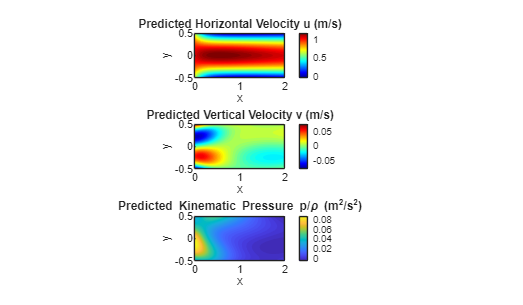

%% Post-Processing: Flow Field Evaluation and Contour Visualization
% Evaluate the trained PINN on a dense structured grid
nx = 200;
ny = 100;
x_vec = linspace(domain(1), domain(2), nx);
y_vec = linspace(domain(3), domain(4), ny);
[X_grid, Y_grid] = meshgrid(x_vec, y_vec);

eval_pts = dlarray([X_grid(:)'; Y_grid(:)'], 'CB');
pred = forward(net, eval_pts);

U_pred = reshape(extractdata(pred(1, :)), [ny, nx]);
V_pred = reshape(extractdata(pred(2, :)), [ny, nx]);
P_pred = reshape(extractdata(pred(3, :)), [ny, nx]);
Speed  = sqrt(U_pred.^2 + V_pred.^2);

% Plot Flow Contours
figure('Position', [100, 100, 1200, 700], 'Color', 'w');

subplot(3, 1, 1);
contourf(X_grid, Y_grid, U_pred, 50, 'LineColor', 'none');
colorbar; colormap(gca, 'jet');
title('Predicted Horizontal Velocity u (m/s)');
xlabel('x'); ylabel('y'); axis equal tight;

subplot(3, 1, 2);
contourf(X_grid, Y_grid, V_pred, 50, 'LineColor', 'none');
colorbar; colormap(gca, 'jet');
title('Predicted Vertical Velocity v (m/s)');
xlabel('x'); ylabel('y'); axis equal tight;

subplot(3, 1, 3);
contourf(X_grid, Y_grid, P_pred, 50, 'LineColor', 'none');
colorbar; colormap(gca, 'parula');
title('Predicted Kinematic Pressure p/\rho (m^2/s^2)');
xlabel('x'); ylabel('y'); axis equal tight;